% Parameters
points_per_mm       =                           .1;
tube_dia            =                        17.08;
Coil_Radious        =                          250;                         % Radius of the slinky coil
Revolution          =                           12;                         % Number of turns
length              =                         3230;
pitch               =           length/ Revolution;
Angle               =         asin(tube_dia/pitch);
slinky_tube_length  = 2*pi*Coil_Radious*Revolution;

points              =                    slinky_tube_length*points_per_mm;
phase               =                                                pi/2;
t                   = linspace(phase, Revolution * 2 * pi+ phase, points);  % Parameter t
 
% Original parametric equations for the slinky
x                   =  pitch * t / (2 * pi);             % Moves along the x-axis
y                   = Coil_Radious * cos(t);             % Circular motion in the y-direction
z                   = Coil_Radious * sin(t);             % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy            = pi - Angle;                        % Angle between X' and Y' ( radians)
theta_xz            =       pi/2;                        % Angle between X' and Z' (90 degrees)
theta_yz            =       pi/2;                        % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T                   = [1, cos(theta_xy),             0;
                       0, sin(theta_xy), cos(theta_yz);
                       0,             0, sin(theta_xz)];

% Apply the transformation to each point
new_coords          =    T * [x; y; z];

% Extract the new coordinates
x_new               = new_coords(1, :);
y_new               = new_coords(2, :);
z_new               = new_coords(3, :);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  slinky start point
%x_new(1)
%y_new(1)
%z_new(1)

% start line start point
sx                  =            min(x_new)

sx = 16.0117

sx_                 = .5*(x_new(1)-sx) + sx;
sy                  =                     0;
sz                  =          Coil_Radious;

% start line
points              = ceil((sx_ -  sx)*points_per_mm);
sline_x             =        linspace(sx, sx_,points);
sline_y             =               ones(1,points)*sy;
sline_z             =               ones(1,points)*sz;

% slinky end  point
%x_new(end)
%y_new(end)
%z_new(end)

% end line start point
ex                  =                        max(x_new);
ex_                 = .5*(ex - x_new(end)) + x_new(end);
ey                  =                                 0;
ez                  =                      Coil_Radious;

% end line
points              =    ceil((ex -  ex_)*points_per_mm);
eline_x             =         linspace( ex_, ex,points );
eline_y             =                  ones(1,points)*ey;
eline_z             =                  ones(1,points)*ez;






% Spline for start connection
points               =                                    ceil((x_new(1) -  sx_)*points_per_mm);
start_connection_x   =                                           linspace(sx_, x_new(1),points);
start_connection_y   = spline([sx_, x_new(1)], [sy, y_new(1)], linspace(sx_, x_new(1), points));
start_connection_z   = spline([sx_, x_new(1)], [sz, z_new(1)], linspace(sx_, x_new(1), points));

% Spline for end connection
points               =                                        ceil((ex_ -  x_new(end))*points_per_mm);
end_connection_x     =                                               linspace(x_new(end), ex_,points);
end_connection_y     = spline([x_new(end), ex_], [y_new(end), ey], linspace(x_new(end), ex_, points));
end_connection_z     = spline([x_new(end), ex_], [z_new(end), ez], linspace(x_new(end), ex_, points));

points               =              ceil((ex -sx)*points_per_mm);
turn_tube_x          =                 linspace( sx, ex, points);
turn_tube_y          =                         ones(1,points)*ey;
turn_tube_z          =   -ones(1,points)*(Coil_Radious+tube_dia);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x_new = [sline_x, start_connection_x, x_new, end_connection_x, eline_x ] 

x_new = 1.0e+03 *

    0.0160    0.0288    0.0417    0.0417    0.0545    0.0673    0.0673    0.0790    0.0907    0.1023    0.1139    0.1255    0.1370    0.1483    0.1596    0.1707    0.1817    0.1925    0.2032    0.2137    0.2240    0.2340    0.2439    0.2535    0.2628    0.2719    0.2807    0.2892    0.2975    0.3054    0.3130    0.3203    0.3272    0.3338    0.3400    0.3459    0.3514    0.3565    0.3613    0.3657    0.3697    0.3733    0.3765    0.3793    0.3817    0.3837    0.3853    0.3865    0.3873    0.3877


y_new = [sline_y, start_connection_y, y_new, end_connection_y, eline_y ] 

y_new =          0         0         0         0    0.0000    0.0000    0.0000   -0.6350   -1.2691   -1.9011   -2.5300   -3.1549   -3.7747   -4.3885   -4.9952   -5.5940   -6.1837   -6.7636   -7.3326   -7.8898   -8.4344   -8.9655   -9.4822   -9.9837  -10.4692  -10.9380  -11.3892  -11.8221  -12.2361  -12.6304  -13.0045  -13.3578  -13.6897  -13.9996  -14.2870  -14.5516  -14.7928  -15.0103  -15.2038  -15.3729  -15.5173  -15.6369  -15.7314  -15.8006  -15.8446  -15.8631  -15.8562  -15.8239  -15.7662  -15.6833


z_new = [sline_z, start_connection_z, z_new, end_connection_z, eline_z ] 

z_new =   250.0000  250.0000  250.0000  250.0000  250.0000  250.0000  250.0000  249.7996  249.1988  248.1984  246.8002  245.0063  242.8197  240.2438  237.2827  233.9413  230.2248  226.1392  221.6912  216.8877  211.7365  206.2459  200.4247  194.2821  187.8281  181.0730  174.0276  166.7032  159.1116  151.2649  143.1757  134.8570  126.3221  117.5847  108.6588   99.5587   90.2990   80.8945   71.3604   61.7118   51.9643   42.1335   32.2352   22.2852   12.2995    2.2940   -7.7151  -17.7119  -27.6802  -37.6042


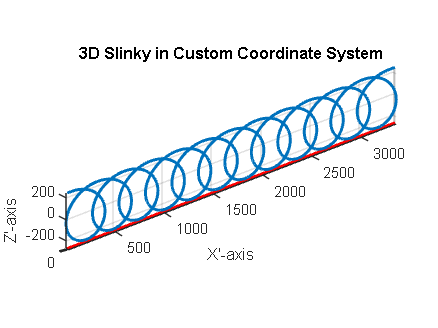




fileID = fopen('slinky_curve_spline01.txt', 'w');
fprintf(fileID, '%f %f %f\n', [x_new; y_new; z_new]);
fileID = fopen('turn_tube_spline01.txt', 'w');
fprintf(fileID, '%f %f %f\n', [turn_tube_x; turn_tube_y; turn_tube_z]);
fclose(fileID);





% Plot the slinky in the new coordinate system
figure;
plot3(  x_new,   y_new,   z_new, 'LineWidth', 2);
hold on
%plot3(sline_x, sline_y, sline_z, 'LineWidth', 2);
%hold on
%plot3(eline_x, eline_y, eline_z, 'LineWidth', 2);


% Plot the start connection
%plot3(start_connection_x, start_connection_y, start_connection_z, 'r', 'LineWidth', 2);
% Plot the end connection
%plot3(  end_connection_x,   end_connection_y,   end_connection_z, 'r', 'LineWidth', 2);
% Plot the turn tube
plot3(  turn_tube_x,   turn_tube_y,   turn_tube_z, 'r', 'LineWidth', 2);
grid on;
xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3);  % Set the view to 3D

% Parameters
points_per_mm       =                           .1;
tube_dia            =                        17.08;
Coil_Radious        =                          250;                         % Radius of the slinky coil
Revolution          =                           12;                         % Number of turns
length              =                         3230;
pitch               =           length/ Revolution;
Angle               =         asin(tube_dia/pitch);
slinky_tube_length  = 2*pi*Coil_Radious*Revolution;

points              =                    slinky_tube_length*points_per_mm;
phase               =                                                pi/2;
t                   = linspace(phase, Revolution * 2 * pi+ phase, points);  % Parameter t
 
% Original parametric equations for the slinky
x                   =  pitch * t / (2 * pi);             % Moves along the x-axis
y                   = Coil_Radious * cos(t);             % Circular motion in the y-direction
z                   = Coil_Radious * sin(t);             % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy            = pi - Angle;                        % Angle between X' and Y' ( radians)
theta_xz            =       pi/2;                        % Angle between X' and Z' (90 degrees)
theta_yz            =       pi/2;                        % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T                   = [1, cos(theta_xy),             0;
                       0, sin(theta_xy), cos(theta_yz);
                       0,             0, sin(theta_xz)];

% Apply the transformation to each point
new_coords          =    T * [x; y; z];

% Extract the new coordinates
x_new               = new_coords(1, :)

x_new = 1.0e+03 *

    0.0673    0.0790    0.0907    0.1023    0.1139    0.1255    0.1370    0.1483    0.1596    0.1707    0.1817    0.1925    0.2032    0.2137    0.2240    0.2340    0.2439    0.2535    0.2628    0.2719    0.2807    0.2892    0.2975    0.3054    0.3130    0.3203    0.3272    0.3338    0.3400    0.3459    0.3514    0.3565    0.3613    0.3657    0.3697    0.3733    0.3765    0.3793    0.3817    0.3837    0.3853    0.3865    0.3873    0.3877    0.3877    0.3873    0.3866    0.3854    0.3839    0.3820


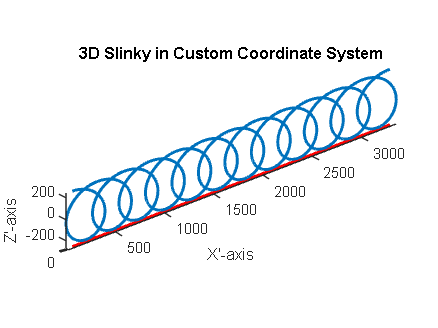

y_new               = new_coords(2, :);
z_new               = new_coords(3, :);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


y_                   =                     round( .5*(min(y_new)+max(y_new)) );
points               =              ceil((x_new(end) -x_new(1))*points_per_mm);
turn_tube_x          =                 linspace( x_new(1), x_new(end), points);
turn_tube_y          =                                       ones(1,points)*y_;
turn_tube_z          =                 -ones(1,points)*(Coil_Radious+tube_dia);



y_new(1)             =           y_;
z_new(1)             = Coil_Radious;

y_new(end)           =           y_;
z_new(end)           = Coil_Radious;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fileID = fopen('slinky_curve_simple01.txt', 'w');
fprintf(fileID, '%f %f %f\n', [x_new; y_new; z_new]);
fileID = fopen('turn_tube_simple01.txt', 'w');
fprintf(fileID, '%f %f %f\n', [turn_tube_x; turn_tube_y; turn_tube_z]);
fclose(fileID);


figure;
plot3(        x_new,         y_new,         z_new,      'LineWidth', 2);      % Plot the slinky in the new coordinate system
hold on
plot3(  turn_tube_x,   turn_tube_y,   turn_tube_z, 'r', 'LineWidth', 2);

xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3);  % Set the view to 3D

% Parameters
points_per_mm       =                           .1;
tube_dia            =                        18.08;
Coil_Radious        =                          250;                         % Radius of the slinky coil
Revolution          =                           12;                         % Number of turns
length              =                         3230;
pitch               =           length/ Revolution;
Angle               =         asin(tube_dia/pitch);
slinky_tube_length  = 2*pi*Coil_Radious*Revolution;
dept                =                         2000;
dept_bend_radious   =                          250;

points              =                    slinky_tube_length*points_per_mm;
phase               =                                                pi/2;
t                   = linspace(phase, Revolution * 2 * pi+ phase, points);  % Parameter t
 
% Original parametric equations for the slinky
x                   =  pitch * t / (2 * pi);             % Moves along the x-axis
y                   = Coil_Radious * cos(t);             % Circular motion in the y-direction
z                   = Coil_Radious * sin(t);             % Circular motion in the z-direction

% Define the custom transformation matrix
theta_xy            = pi - Angle;                        % Angle between X' and Y' ( radians)
theta_xz            =       pi/2;                        % Angle between X' and Z' (90 degrees)
theta_yz            =       pi/2;                        % Angle between Y' and Z' (90 degrees)

% Transformation matrix for custom coordinate system
T                   = [1, cos(theta_xy),             0;
                       0, sin(theta_xy), cos(theta_yz);
                       0,             0, sin(theta_xz)];

% Apply the transformation to each point
new_coords          =    T * [x; y; z];

% Extract the new coordinates
x_new               = new_coords(1, :);
y_new               = new_coords(2, :);
z_new               = new_coords(3, :);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


y_                   =                   round(.5*(min(y_new)+max(y_new)));
turn_tube_x          =                              [x_new(1), x_new(end)];
turn_tube_y          =                                            [y_, y_];
turn_tube_z          = -[(Coil_Radious+tube_dia), (Coil_Radious+tube_dia)];



y_new(1)             =           y_;
z_new(1)             = Coil_Radious;

y_new(end)           =           y_;
z_new(end)           = Coil_Radious;

% center of end u bend
c_ute_x              =                                  x_new(end);
c_ute_y              =                                          y_;
c_ute_z              =          .5*(turn_tube_z(end) + z_new(end));

r_ute                =     abs(.5*(turn_tube_z(end) - z_new(end)));
phase_ute            =                                      3*pi/2;
points               =                ceil(pi*r_ute*points_per_mm);
t                    = linspace(pi + phase_ute,phase_ute,  points);

ute_x                =                    c_ute_x + r_ute * cos(t);
ute_y                =                     ones(1, points)*c_ute_y;
ute_z                =                    c_ute_z + r_ute * sin(t);

% center of inlet bend

c_itb_x              =                                    x_new(1);
c_itb_y              =                y_new(1) + dept_bend_radious;
c_itb_z              =                                    z_new(1); % constant


points               = ceil(pi*.5*dept_bend_radious*points_per_mm);
t                    =                linspace(pi, 3*pi/2, points);

itb_x                =        c_itb_x + dept_bend_radious * cos(t);
itb_y                =        c_itb_y + dept_bend_radious * sin(t);     
itb_z                =                     ones(1, points)*c_itb_z;

otb_x                =                             itb_x(end:-1:1);
otb_y                =                             itb_y(end:-1:1);
otb_z                =                   itb_z(end:-1:1) - 2*r_ute;

in_tube_x            =                         [itb_x(1),itb_x(1)]

in_tube_x =  -182.7083 -182.7083


in_tube_y            = [itb_y(1)+dept-dept_bend_radious, itb_y(1)]

in_tube_y = 1.0e+03 *

    2.0000    0.2500


in_tube_z            =                        [itb_z(1), itb_z(1)]

in_tube_z =    250   250





out_tube_x =                               [otb_x(end),otb_x(end)]

out_tube_x =  -182.7083 -182.7083


out_tube_y =   [otb_y(end), otb_y(end) + dept - dept_bend_radious]

out_tube_y = 1.0e+03 *

    0.2500    2.0000


out_tube_z =                              [otb_z(end), otb_z(end)]

out_tube_z =  -268.0800 -268.0800


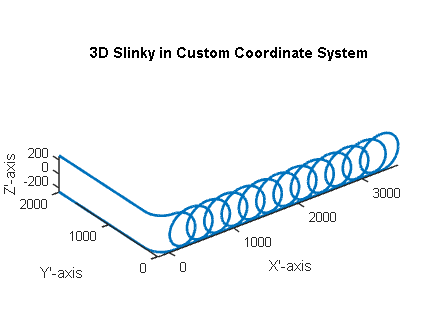


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Co_ordinates = [ in_tube_x(1:end-1), itb_x(1:end-1), x_new(1:end-1), ute_x(1:end-1), turn_tube_x(1:end-1), otb_x(1:end-1),out_tube_x ;
                 in_tube_y(1:end-1), itb_y(1:end-1), y_new(1:end-1), ute_y(1:end-1), turn_tube_y(1:end-1), otb_y(1:end-1),out_tube_y ;
                 in_tube_z(1:end-1), itb_z(1:end-1), z_new(1:end-1), ute_z(1:end-1), turn_tube_z(1:end-1), otb_z(1:end-1),out_tube_z];


fileID = fopen('1.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ in_tube_x(1:end); in_tube_y(1:end); in_tube_z(1:end)]);

fileID = fopen('2.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ itb_x(1:end); itb_y(1:end); itb_z(1:end)]);


fileID = fopen('3.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ x_new(1:end); y_new(1:end); z_new(1:end)]);


fileID = fopen('4.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ ute_x(1:end); ute_y(1:end); ute_z(1:end)]);


fileID = fopen('5.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ turn_tube_x(1:end); turn_tube_y(1:end); turn_tube_z(1:end)]);


fileID = fopen('6.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ otb_x(1:end); otb_y(1:end); otb_z(1:end)]);


fileID = fopen('7.txt', 'w');
fprintf(fileID, '%f %f %f\n', [ out_tube_x(1:end); out_tube_y(1:end); out_tube_z(1:end)]);

%m1 = Co_ordinates(1,:) == Co_ordinates(2,:)
%m2 = (Co_ordinates(1,:) == Co_ordinates(3,:))
%ind =m1 & m2
%Co_ordinates(1,ind)


fileID = fopen('Co_ordinatesPP.txt', 'w');
fprintf(fileID, '%f %f %f\n', Co_ordinates);



figure;
plot3(   Co_ordinates(1,:),    Co_ordinates(2,:),    Co_ordinates(3,:),      'LineWidth', 2);
%plot3(   out_tube_x,    out_tube_y,    out_tube_z,      'LineWidth', 2);      % 
%hold on
%plot3(    in_tube_x,     in_tube_y,     in_tube_z,      'LineWidth', 2);      % 
%hold on
%plot3(        otb_x,         otb_y,         otb_z,      'LineWidth', 2);      % 
%hold on
%plot3(        itb_x,         itb_y,         itb_z,      'LineWidth', 2);      % 
%hold on
%plot3(        ute_x,         ute_y,         ute_z,      'LineWidth', 2);      % 
%hold on
%plot3(        x_new,         y_new,         z_new,      'LineWidth', 2);      % Plot the slinky in the new coordinate system
%hold on
%plot3(  turn_tube_x,   turn_tube_y,   turn_tube_z, 'r', 'LineWidth', 2);

xlabel('X''-axis');
ylabel('Y''-axis');
zlabel('Z''-axis');
title(['3D Slinky in Custom Coordinate System']);
axis equal;
view(3);  % Set the view to 3D